clc
clear
close all

fs = 100000;     % Sampling frequency
t = 0:1/fs:0.02; % Time vector

fm = 500;        % Message frequency
fc = 5000;       % Carrier frequency
mu = 0.7;        % Modulation index

m = cos(2*pi*fm*t);

c = cos(2*pi*fc*t);

am = (1 + mu*m).*c;

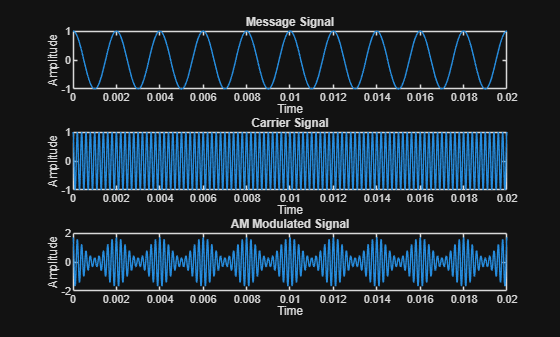

figure

subplot(3,1,1)
plot(t,m)
title('Message Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(3,1,2)
plot(t,c)
title('Carrier Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(3,1,3)
plot(t,am)
title('AM Modulated Signal')
xlabel('Time')
ylabel('Amplitude')

rectified = abs(am);

[b,a] = butter(5, fm/(fs/2));
demod = filter(b,a,rectified);

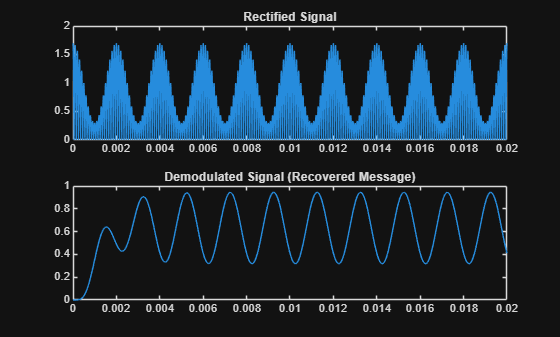

figure

subplot(2,1,1)
plot(t,rectified)
title('Rectified Signal')

subplot(2,1,2)
plot(t,demod)
title('Demodulated Signal (Recovered Message)')

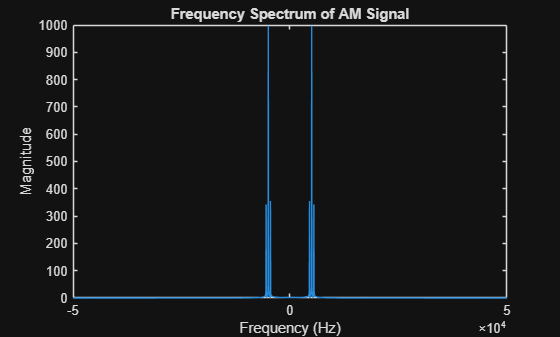

figure
fft_am = abs(fft(am));
f = linspace(-fs/2, fs/2, length(fft_am));

plot(f,fftshift(fft_am))
title('Frequency Spectrum of AM Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')